Lab3 第一題

X1 = [4 3 7 -9 1 0 0];
fft(X1)

ans =    6.0000 + 0.0000i  11.5206 - 4.8312i  -7.9623 - 7.7059i   7.4417 +13.9204i   7.4417 -13.9204i  -7.9623 + 7.7059i  11.5206 + 4.8312i


fft(X1, 8)

ans =    6.0000 + 0.0000i  11.4853 - 2.7574i  -2.0000 -12.0000i  -5.4853 +11.2426i  18.0000 + 0.0000i  -5.4853 -11.2426i  -2.0000 +12.0000i  11.4853 + 2.7574i


fft(X1, 6)

ans =    6.0000 + 0.0000i  10.5000 - 7.7942i -10.5000 + 2.5981i  18.0000 + 0.0000i -10.5000 - 2.5981i  10.5000 + 7.7942i


X1 = [1 2 3 4 5; 5 6 7 8 9; 7 6 5 4 3; 2 4 2 1 6];
fft(X1) %X1 is a 1x7 vector, fft(x1) still is a 1x7 vector

ans =   15.0000 + 0.0000i  18.0000 + 0.0000i  17.0000 + 0.0000i  17.0000 + 0.0000i  23.0000 + 0.0000i
  -6.0000 - 3.0000i  -4.0000 - 2.0000i  -2.0000 - 5.0000i   0.0000 - 7.0000i   2.0000 - 3.0000i
   1.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -7.0000 + 0.0000i
  -6.0000 + 3.0000i  -4.0000 + 2.0000i  -2.0000 + 5.0000i   0.0000 + 7.0000i   2.0000 + 3.0000i


        %If X1 is a 4x5 matrix, fft(X1) will be a 4x5 matrix.
        %The structure of X1 won't be changed.

Lab3 第二題

N = 256, fs = 1000;

N = 256

freqStep = fs/N;
time = (0:N-1)/fs;
y = 0.5*sin(2*pi*50*time) + sin(2*pi*120*time);
Y = fft(y)

Y =    3.3191 + 0.0000i   3.3275 + 0.1645i   3.3533 + 0.3337i   3.3981 + 0.5130i   3.4652 + 0.7090i   3.5599 + 0.9308i   3.6911 + 1.1921i   3.8744 + 1.5154i   4.1384 + 1.9408i   4.5420 + 2.5499i   5.2281 + 3.5397i   6.6565 + 5.5435i  11.5842 +12.3557i -32.3562 -48.1012i  -2.9710 - 7.6422i  -0.2343 - 3.8708i   0.8498 - 2.3837i   1.4741 - 1.5405i   1.9168 - 0.9600i   2.2801 - 0.5041i   2.6139 - 0.1075i   2.9495 + 0.2681i   3.3133 + 0.6513i   3.7333 + 1.0697i   4.2475 + 1.5575i   4.9151 + 2.1656i   5.8422 + 2.9830i   7.2453 + 4.1899i   9.6569 + 6.2274i  14.8447 +10.5586i  34.3917 +26.7662i -85.5819 -72.4501i -18.0798 -16.5749i  -9.7828 - 9.6802i  -6.5412 - 6.9692i  -4.8122 - 5.5110i  -3.7369 - 4.5948i  -3.0033 - 3.9624i  -2.4708 - 3.4975i  -2.0668 - 3.1398i  -1.7499 - 2.8550i  -1.4946 - 2.6220i  -1.2847 - 2.4273i  -1.1092 - 2.2617i  -0.9602 - 2.1188i  -0.8323 - 1.9939i  -0.7214 - 1.8836i  -0.6243 - 1.7852i  -0.5386 - 1.6968i  -0.4626 - 1.6168i


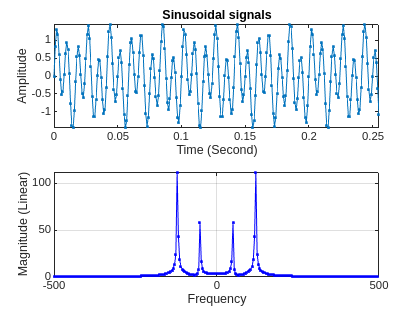

Y = fftshift(Y);
f = 10*freqStep;
subplot(211);
plot(time, y, '.-');
title('Sinusoidal signals');
xlabel('Time (Second)');
ylabel('Amplitude');
axis tight;
freq = freqStep*(-N/2:N/2-1);
subplot(212);
plot(freq, abs(Y), '.-b');
grid on;
xlabel('Frequency');
ylabel('Magnitude (Linear)');

Lab3 第三題

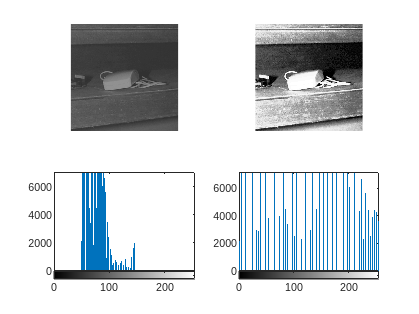

figure;
image_1 = imread('l5_1.bmp');
image_2 = histeq(image_1);
subplot(221);   imshow(image_1);
subplot(222);   imshow(image_2);    %After image processing, image_2 has more contrast.
subplot(223);   imhist(image_1);
subplot(224);   imhist(image_2);    %After image processing, the distribution is more dispersed.

Lab3 第四題

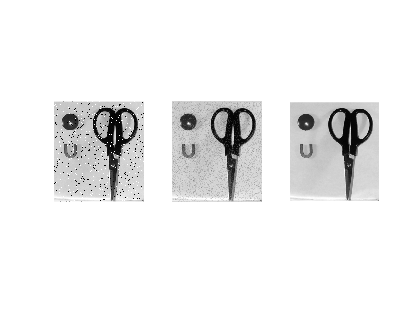

figure;
image = imread('l5_2.bmp');
image_noisy = imnoise(image, 'salt & pepper', 0.06);
image2_noisy = double(image_noisy)/255;
h = [1/9 1/9 1/9; 1/9 1/9 1/9; 1/9 1/9 1/9];
image_low = filter2(h, image2_noisy);
image_med = medfilt2(image_noisy, [3 3]);
subplot(131);   imshow(image_noisy);
subplot(132);   imshow(image_low);
subplot(133);   imshow(image_med);

%After using low pass filter, thw white dots in the first figure has
%removed. After median pass filter, all the white and black dots are gone.

Lab3 第五題

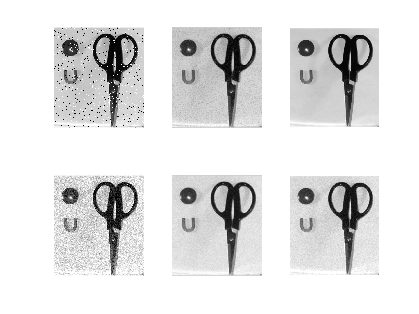

figure;
image = imread('l5_2.bmp');
image_noisy = imnoise(image, 'salt & pepper', 0.06);
image2_noisy = double(image_noisy)/255;
h = [1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25;1/25 1/25 1/25 1/25 1/25;1/25 1/25 1/25 1/25 1/25;1/25 1/25 1/25 1/25 1/25];
image_low = filter2(h, image2_noisy);
image_med = medfilt2(image_noisy, [5 5]);
subplot(231);   imshow(image_noisy);
subplot(232);   imshow(image_low);
subplot(233);   imshow(image_med);
image_noisy = imnoise(image, 'gaussian', 0.06);
image2_noisy = double(image_noisy)/255;
image_low = filter2(h, image2_noisy);
image_med = medfilt2(image_noisy, [5 5]);
subplot(234);   imshow(image_noisy);
subplot(235);   imshow(image_low);
subplot(236);   imshow(image_med);

%The Gaussian noise makes the figure brighter, also the figures after the filters
%processing.

Lab3 第六題

data = load("data1.txt");
for i = 1:10
    newdata = data * i;
    filename = ['newdata_' num2str(i) '.txt'];
    fileID = fopen(filename, 'w');
    writematrix(newdata, filename, 'Delimiter', 'tab');
end
fileID = fopen('alldata.txt', 'w');
allData = [];
for i = 1:10
    newData = load(['newdata_', int2str(i), '.txt']);
    allData = [allData; newData];
end
writematrix(allData, 'alldata.txt', 'Delimiter', 'tab');